Irms=10;%A
Imax=10;%A
Ipk=Irms/(sqrt(0.5/3));
diameter=10/Ipk %mm^2

diameter = 0.4082

airgap=3*0.00030480*2; %m
L=20*10^(-6); %H
Al=3700*10^(-3); %H/turn^2
Mr=3300; %Relative permability of core
M0=1.25663706212*10^(-6); %H/M
Bsat=200/1000;%T
Ae=125.2/10^6/2;%m^2 74.2mm
Ae=76/10^6;
Acmin=59.1/10^6;%m^2w
Le=45.7/1000;%m
Rc=Le/(M0*Mr*Ae);
Rg=airgap/(M0*Ae);
Re=Rg+Rc

Re = 1.9294e+07

N=sqrt(L/Re^(-1))

N = 19.6438

w=(1/2)*L*Imax^2;
phimax=Bsat*Acmin;%tesla
Re_low=2*w/phimax^2

Re_low = 1.4315e+07

Aw=14.3*(18-8.8)*10^(-6);
Kf=1;
Jmax=10*1000000;
Fmax=Jmax*Aw*Kf;
Re_high=Fmax^2/(2*w)

Re_high = 8.6540e+08

min_turn=L*Imax/(phimax)%Turns

min_turn = 16.9205

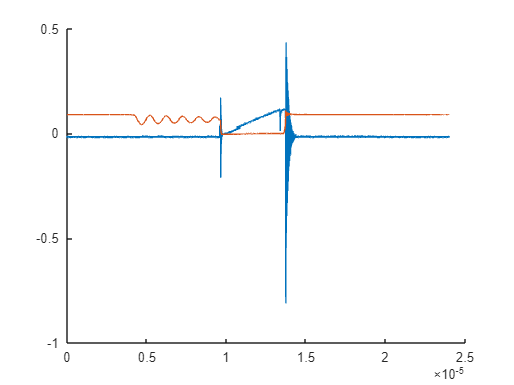

clf
T = table2array(readtable("C:\Users\cbabe\Documents\Power Electronics\NewFolder1\NewFile1.csv",'NumHeaderLines',3));
hold on
plot(2.000000e-09*T(:,1),T(:,2));
plot(2.000000e-09*T(:,1),T(:,3));
hold off


Voltage1=4.66;%V
Current1=0.3;%A

Voltage2=8.5;%V
Current2=0.87;%A